# **Lab5 - LQR (Linear Quadratic Regulator)**

**Fie sistemul liniar si invariant in timp (LTI)** care are modul nominal de functionare $M_n :\dot{x_n } \left(t\right)=A_n x_n \left(t\right)+B_n u_n \left(t\right)$, unde $x\left(t_0 \right)=x_0$ este conditia initiala, iar $\left\lbrace \begin{array}{l}
A_n \in {\mathbb{R}}^{\textrm{nxn}} \\
B_n \in {\mathbb{R}}^{\textrm{nxm}} 
\end{array}\right.$ cu $\left\lbrace \begin{array}{l}
x\left(t\right)\in {\mathbb{R}}^n \\
u\left(t\right)\in {\mathbb{R}}^m 
\end{array}\right.$ vectorul de stare, respectiv cel de comanda

Acesta este un **obiectiv liniar patratic** care implica functionala patratica, mai specific suma de 2 forme patratice (la stare si comanda). Fie acestea $x_n^T Q_n x_n +u_n^T R_n u_n$. Daca integram asta in timpm obtinem $\int_0^T \left\lbrack x_n^T Q_n x_n +u_n^T R_n u_n \right\rbrack \textrm{dt}=\min \;J$, unde J este functia de cost. Acest T poate fi ori pe orizont finit de timp, ori infinit.

Observam ceva interesant aici: cine sunt acei $Q_n \;\textrm{si}\;R_n$? Ele se numesc matrici de penalizare patratice si au urmatoarele proprietati: $Q_n :\left\lbrace \begin{array}{l}
\textrm{simetrica}\\
\textrm{pozitiv}\;\textrm{semidefinita}\;\left(Q_n \succeq 0\right)\\
\textrm{Admite}\;\textrm{factorizare}\;\textrm{Cholescky}:Q_n =\bar{Q_n^T } *\bar{Q_n } 
\end{array}\right.$, iar $R_n :\left\lbrace \begin{array}{l}
\textrm{simetrica}\\
\textrm{pozitiv}\;\textrm{DEFINITA}\left(R_n \succ 0\right)
\end{array}\right.$

$\left\lbrace \begin{array}{l}
Q_n \;\textrm{penalizeaza}\;\textrm{starile}\;\left(\textrm{perfomanta}\right)\\
R_n \;\textrm{penalizeaza}\;\textrm{efortul}
\end{array}\right.$, ambele matrici diagonale

Aceste 2 matrici de penalizare se iau empiric, adica prin "trial and error". Presupunem aici ca starile si intrarile nu sunt cuplate

## Factorizarea Cholesky

Aici ideea e ca noi calculam $Q_n =\bar{Q_n^T } *\bar{Q_n }$. Insa noi stim ca $Q_n =Q_n^T$. Deci noi practic aflam doar o matrice, si anume $\bar{Q_n }$ inferior triunghiulara, iar dupa o transpunem

$Q_n^T$ = chol(Q) functie matlab

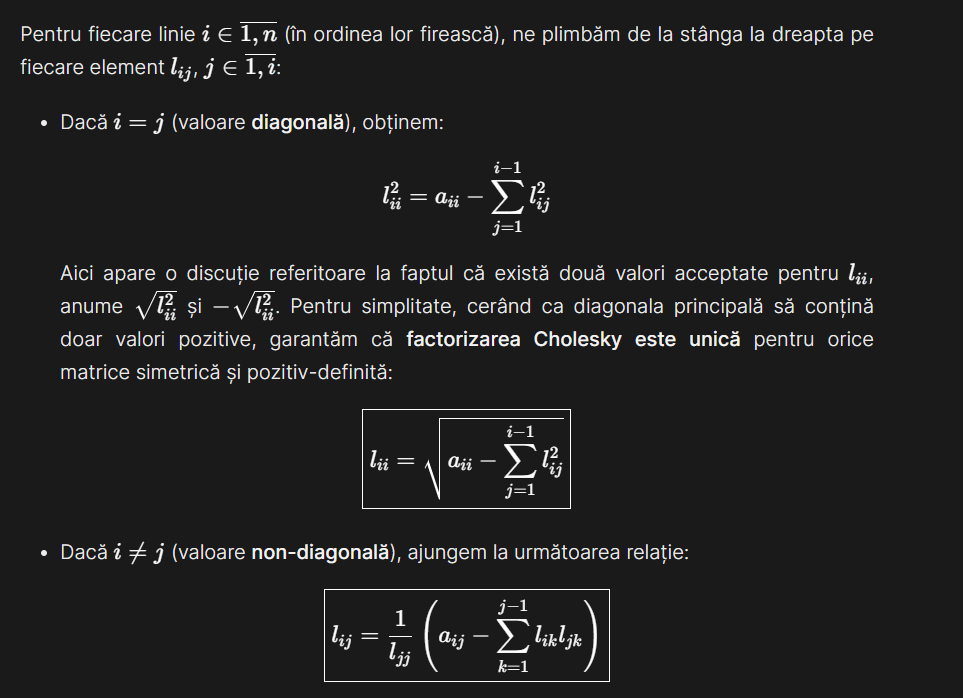

Ce scop avem? Sa dam o lege de comanda $u_n \left(t\right)=-K_n x_n \left(t\right)$, unde $K_n$ minim. Acesta se calculeaza din $K_n =R_n^{-1} B_n^T P$, unde $P\in {\mathbb{R}}^{\textrm{nxn}} \;\textrm{cu}\;P^T =P>0$ trebuie determinat. Acesta se afla din Ecuatia Algebrica a lui **Riccati** pe caz continuu (CARE): $A_n^T P_n +P_n A_n -{P_n B_n R}_n^{-1} B_n^T P_n +Q_n =0$.

Observam aici ca **Ecutia Algebrica a lui Riccati** are 3 termeni:$\left\lbrace \begin{array}{l}
\textrm{Termen}\;\textrm{Lyapunov}:A_n^T P_n +P_n A_n \;\\
\textrm{Termen}\;\textrm{Riccati}\;\left(\textrm{este}\;\textrm{patratic}\right):{{-P}_n B_n R}_n^{-1} B_n^T P_n \;\\
\textrm{Termen}\;\textrm{liber}:Q_n 
\end{array}\right.$

**Aceasta ecuatie are mai multe solutii **$K_n$**, insa una singura stabilizeaza sistemul in bucla inchisa**

Dupa ce se afla $K_n$, **sistemul nominal in bucla inchisa arata asa**: $\hat{M_n } :\dot{x} \left(t\right)=\hat{A_n } x_n \left(t\right),\textrm{unde}\;\;\hat{A_n } =A_n -B_n K_n$. Acest sistem este stabil in bucla inchisa, unde $\hat{A_n } \in {\mathbb{R}}^{\textrm{nxn}}$ este matricea nominala in bucla inchisa. Mai mult, daca am aflat $K_n$, avem garantia ca $J$ ia valoare minima: $J_n =x_0^T {\textrm{Px}}_0 \equiv J^*$

**Ce trebuie neaparat? **$\textrm{minim}\left\lbrace \begin{array}{l}
\left(A_n ,B_n \right)\;\textrm{stabilizabila}\\
\left(\bar{Q_n } ,A_n \right)\textrm{detectabila}
\end{array}\right.$

## Acum sa presupunem ca avem defecte

Fie $A_f ,B_f$ matrici pentru modelul avariat, cu $\left(A_f ,B_f \right)\not= \left(A_n ,B_n \right)$. In acest sens, avem $M_f :\dot{x_f } \left(t\right)=A_f x_f \left(t\right)+B_f u_f \left(t\right)$.

Ecuatia lui **Riccati** va arata asa: $A_f^T P_f +P_f A_f -{P_f B_f R}_n^{-1} B_f^T P_f +Q_n =0$. Cu $\left\lbrace \begin{array}{l}
\left(A_f ,B_f \right)\;\textrm{stabilizabila}\\
\left(\bar{Q_n } ,A_f \right)\textrm{detectabila}
\end{array}\right.$, se afla $P_f >0$, de unde aflam $K_f =R_n^{-1} B_f^T P_f$, si apoi legea de comanda $u_f \left(t\right)={-K}_f x_f \left(t\right)$. in acest sens, sistemul in bucla inchisa $\hat{M_f } :\dot{x_f } \left(t\right)=\hat{A_f } x_f \left(t\right)$, unde $\hat{A_f } =A_f -B_f K_f$ este matricea sistemului in bucla inchisa dupa defecte. Functia minima de cost este: $J_f =J_n +x_f^T \left(P_f -P\right)x_f$

Aceleasi conditii si aici, $\textrm{minim}\left\lbrace \begin{array}{l}
\left(A_f ,B_f \right)\;\textrm{stabilizabila}\\
\left(\bar{Q_n } ,A_f \right)\textrm{detectabila}
\end{array}\right.$

Pentru a rezolva CARE pentru sisteme pana in ordinul 3, se poate face manual. Pentru ordin mare, se folosesc diferite metode pentru a rezolva ecuatia lui **Riccati**

- *Metoda vectorilor Schur *(pornește de la *Forma Schur a unei matrice***)**

- *Metoda Kleinman-Newton* (pornește de la *Metoda Newton*)

- *Metoda Sign-Matrix*

*Uite aici video de cum ajung de la *$J\to \textrm{Riccati}$

[https://www.youtube.com/watch?v=ZktL3YjTbB4](https://www.youtube.com/watch?v=ZktL3YjTbB4)

# **Metoda Vectorilor Schur**

Aceasta este una din solutiile folosite la sistemele de ordin mare pentru a rezolva ecuatia lui **Riccati**. Aceasta metoda este una de tip spatiu invariant

### Pana sa intram in aceasta metoda, sa clarificam cateva lucruri:

#### Forma Schur a unei matrici A

Aceasta se scrie $A={\textrm{USU}}^T$, unde $\left\lbrace \begin{array}{l}
U^T U=I\Rightarrow \Lambda \left(S\right)=\Lambda \left(A\right),\;U\;\textrm{matrice}\;\textrm{ortogonala}\\
S\;\textrm{este}\;o\;\textrm{matrice}\;\textrm{superior}\;\textrm{triunghiulara}\;\textrm{care}\;\textrm{are}\;\textrm{pe}\;D\ldotp P\;\;\textrm{valorile}\;\textrm{proprii}
\end{array}\right.$

#### Matrice ortogonala: $U^T =U^{-1}$

clear
close all
clc

A = [1 4 3;
     9 1 3;
     7 5 4];

help schur

 schur - Schur decomposition
    This MATLAB function returns the Schur matrix of A.

    Syntax
      T = schur(A)
      T = schur(A,mode)
      [U,T] = schur(___)

    Input Arguments
      A - Input matrix
        square matrix
      mode - Schur form system
        "real" (default) | "complex"

    Output Arguments
      U - Schur vectors
        unitary matrix
      T - Schur matrix
        square matrix

    Examples
      Schur Form of Matrix
  


[U,S] = schur(A)

U =    -0.4095   -0.6385   -0.6516
   -0.5488    0.7430   -0.3831
   -0.7288   -0.2007    0.6547


S =    11.6992    3.5029    5.2524
         0   -4.9578   -2.2675
         0         0   -0.7413



disp('Asa se scrie Schur');

Asa se scrie Schur


norm(A - U * S * U')

ans = 1.2940e-14


disp('Valori proprii ale lui A')

Valori proprii ale lui A


eig(A)

ans =    11.6992
   -4.9578
   -0.7413


Aici se vede ca U este ortogonala

Utranspus = U'

Utranspus =    -0.4095   -0.5488   -0.7288
   -0.6385    0.7430   -0.2007
   -0.6516   -0.3831    0.6547



eye(3) / U

ans =    -0.4095   -0.5488   -0.7288
   -0.6385    0.7430   -0.2007
   -0.6516   -0.3831    0.6547


#### Matrice antisimetrica J

O matrice **patratica** J este antisimetrica $\Leftrightarrow J^T =-J$.  Asta inseamna ca transpusa unei matrici este negativa ei

#### Matrice Hamilton $H$

Mai intai sa luam matricea antisimetric $J=\left\lbrack \begin{array}{cc}
0_n  & I_n \\
-I_n  & 0_n 
\end{array}\right\rbrack$. O matrice Hamilton $H\in {\mathbb{R}}^{2\textrm{nx2n}}$ respecta urmatoarea egalitate: ${\left(\textrm{JH}\right)}^T =\textrm{JH}$. In acest sens, are simetrie a spectrului in raport cu axa imaginara, adica daca avem $\lambda ,\textrm{avem}\;\textrm{si}\;\bar{\lambda} ,-\lambda \;\textrm{si}-\bar{\lambda}$ **si nu are poli pe axa imaginara**

## Ok, acum ca am clarificat aceste chestii, sa trecem la **Metoda Vectorului Schur**

**Pana sa intram aici, sa vedem de unde scoatem:**

- **Construim matricea Hamilton** pentru sistem avariat: $H_f =\left\lbrack \begin{array}{cc}
A_f  & -B_f R_n^{-1} B_f^T \\
-Q_n  & -A_f^T 
\end{array}\right\rbrack$

- Se aduce $H_f$ la Forma Schur Reala (FSR)  superior (cvasi-) triunghilara, si se scrie ca $S_f =U_f^T H_f U_f$

- Scriem $\left\lbrace \begin{array}{l}
S_f =\left\lbrack \begin{array}{cc}
S_{f_{11} }  & S_{f_{12} } \\
0 & S_{f_{22} } 
\end{array}\right\rbrack \\
U_f =\left\lbrack \begin{array}{cc}
U_{f_{11} }  & U_{f_{12} } \\
U_{f_{21} }  & U_{f_{22} } 
\end{array}\right\rbrack 
\end{array}\right.$. De mentionat: primele n coloane ale lui $U_f$, mai exact $\left\lbrack \begin{array}{c}
U_{f_{11} } \\
U_{f_{21} } 
\end{array}\right\rbrack$ subintind spatiul invariant si stabil al lui $H_f$. **Aceasta exprimare pompoasa inseamna ca aceste n coloane corespund valorilor proprii stabile: **$\lambda_i \in \Lambda \left(S_f \right),\textrm{Re}\left(\lambda_i \right)<0$**. Mai precis, aceste valori stabile sunt in **$S_{f_{11} }$

- Solutia ecuatiei **Riccati** este $P_f =U_{f_{21} } U_{f_{11} }^{-1}$

- Obtinem $\Lambda \left({S_f }_{11} \right)=\Lambda \left(A_f -B_f R_n^{-1} B_f^T P_f \right)\in {\mathbb{C}}^-$

De ce ne uitam pe $S_{f_{11} }$ la valorile stabile? De ce sunt ele acolo? 

- Conform FSR (sau RSF in engleza), transformarea ortogonala a matricii $U_f$ poate fi scrisa astfel incat plasarea valorilor principale ale lui $A_f$ pe $S_f$ sa fie scrise asa cum vrem

- Cum am mentionat mai sus, o matrie Hamilton are valorile proprii simetrice pe axa imaginara. Stiind ca sistemul **NU ARE VALORI PROPRII PE AXA IMAGINARA,** iar dimensiunea matricii Hamilton $H\in {\mathbb{R}}^{2\textrm{nx2n}}$, n valori proprii sunt stabile, iar restul de n instabile

- Pentru a rezolva CARE, avem nevoie de o baza a subspatiului invariant stabil. **Metoda Schur** aplica transformari ortogonale pentru a "aranja" elementele din $S_f$, fortand partile stabile in matricea bloc $S_{f_{11} }$

- Prin aceasta fortare, primele n coloane din matricea $U_f$ vor cuprinde exact subspatiul invariant stabil de care avem nevoie

## **Fun fact la matricile Hamiltoniene: Urma lor (trace) este 0. De ce?**

#### Pana sa intru in motiv, sa reamintim ce este aia urma unei matrici (trace of a matrix):

Urma unei matrici este neironic suma elementelor de pe Diagonala Principala (DP). Asadar, daca transpun o matrice patrata, o sa am aceeasi urma $\textrm{tr}\left(A\right)=\textrm{tr}\left(A^T \right)$

#### Acum sa ne uitam la matricea Hamilton a noastra


$$H_f =\left\lbrack \begin{array}{cc}
A_f  & -B_f R_n^{-1} B_f^T \\
-Q_n  & -A_f^T 
\end{array}\right\rbrack$$


Stim ca transpusa unei matrici patrate este aceeasi. Insa, daca vedem, noi negam transpusa. O sa iau o matrice $A_f$ de 4 dimensiuni pentru a vedea precis cum arata pe cazul generic $A_f \in {\mathbb{R}}^{n\times n}$

$A_f =\left\lbrack \begin{array}{cccc}
a_{f_{11} }  & a_{f_{12} }  & a_{f_{13} }  & a_{f_{14} } \\
a_{f_{21} }  & a_{f_{22} }  & a_{f_{23} }  & a_{f_{24} } \\
a_{f_{31} }  & a_{f_{32} }  & a_{f_{33} }  & a_{f_{34} } \\
a_{f_{41} }  & a_{f_{42} }  & a_{f_{43} }  & a_{f_{44} } 
\end{array}\right\rbrack$. Nu o sa mai transpun matricea, incat Elementele de pe diagonala principala nu se modifica. Acum o sa neg matricea: $-A_f^T =\left\lbrack \begin{array}{cccc}
-a_{f_{11} }  & {-a}_{f_{21} }  & -a_{f_{31} }  & {-a}_{f_{41} } \\
-a_{f_{12} }  & {-a}_{f_{22} }  & -a_{f_{32} }  & {-a}_{f_{42} } \\
-a_{f_{13} }  & -a_{f_{23} }  & {-a}_{f_{33} }  & -a_{f_{43} } \\
-a_{f_{14} }  & -a_{f_{24} }  & {-a}_{f_{34} }  & {-a}_{f_{44} } 
\end{array}\right\rbrack$. Acum daca fac $\mathrm{tr}\left(H_f \right)=\mathrm{tr}\left(A_f \right)-\mathrm{tr}\left(-A_f^T \right)=a_{f_{11} } +a_{f_{22} } +a_{f_{33} } +a_{f_{44} } -\left(a_{f_{11} } +a_{f_{22} } +a_{f_{33} } +a_{f_{44} } \right)=0$

## Acum facem un model concret

### Prima cerinta

clear
close all
clc

load("E:\Radu editing document\SS + TCAI + TSA\CO + RSA\CO+RSA\CO+RSA\CO\Lab_Daniel\RCAM.mat");

Luam sistemul longitudinal si il consideram nominal

A_lon

A_lon =    -0.9800    0.0000   -0.0006   -0.0160
    1.0000         0         0         0
   -2.2000   -9.8000   -0.0330    0.0740
   77.0000   -0.7700   -0.2300   -0.6700


B_lon

B_lon =    -2.4000    0.2900
         0         0
    0.1800    9.8000
   -6.5000         0



Q = diag([10 30 20 25])

Q =     10     0     0     0
     0    30     0     0
     0     0    20     0
     0     0     0    25



R = diag([5 6])

R =      5     0
     0     6



[P,K] = icare(A_lon,B_lon,Q,R)

P = 1.0e+04 *

    0.0027    0.0475   -0.0001   -0.0004
    0.0475    1.3740   -0.0012   -0.0168
   -0.0001   -0.0012    0.0001    0.0000
   -0.0004   -0.0168    0.0000    0.0003


K =    -7.4384   -9.6912    0.1263   -2.0488
    0.3137    3.0932    1.8155    0.0523


Aici vedem lqr

[K,P] = lqr(A_lon,B_lon,Q,R)

K =    -7.4384   -9.6912    0.1263   -2.0488
    0.3137    3.0932    1.8155    0.0523


P = 1.0e+04 *

    0.0027    0.0475   -0.0001   -0.0004
    0.0475    1.3740   -0.0012   -0.0168
   -0.0001   -0.0012    0.0001    0.0000
   -0.0004   -0.0168    0.0000    0.0003


Aici P este solutia CARE, iar $K=R^{-1} B^T P$

Acum facem initial ala

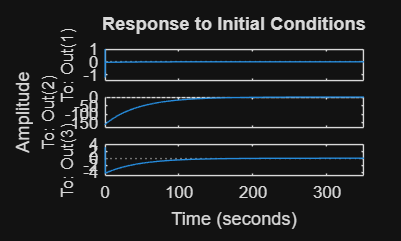

x0 = [1;
      2;
      3;
      4];


ss_bi = ss(A_lon - B_lon * K, B_lon, C_lon, D_lon);

figure
initial(ss_bi, x0)

Acum vedem valorile proprii ale sistemului in bucla inchisa

eig(ss_bi)

ans =  -16.4573 +12.5936i
 -16.4573 -12.5936i
  -0.0220 + 0.0000i
 -17.8213 + 0.0000i



eig(A_lon - B_lon * K)

ans =  -16.4573 +12.5936i
 -16.4573 -12.5936i
  -0.0220 + 0.0000i
 -17.8213 + 0.0000i


### A doua cerinta

Pana sa ma apuc de cerinta, sa scoatem cholesky ala

Qtilde = chol(Q)

Qtilde =     3.1623         0         0         0
         0    5.4772         0         0
         0         0    4.4721         0
         0         0         0    5.0000


Acum vedem stabilizarea si detectabilitatea

Pc = ctrb(A_lon, B_lon)

Pc =    -2.4000    0.2900    2.4559   -0.2906    0.4779   -0.0358   -5.4437    0.6088
         0         0   -2.4000    0.2900    2.4559   -0.2906    0.4779   -0.0358
    0.1800    9.8000    4.7931   -0.9614    4.6029   -0.6854   -2.2736    0.2978
   -6.5000         0 -180.4864   20.0760  310.7745  -35.8270 -174.3702   21.6264



Po = obsv(A_lon, Qtilde)

Po =     3.1623         0         0         0
         0    5.4772         0         0
         0         0    4.4721         0
         0         0         0    5.0000
   -3.0990    0.0000   -0.0021   -0.0506
    5.4772         0         0         0
   -9.8387  -43.8269   -0.1476    0.3309
  385.0000   -3.8500   -1.1500   -3.3500
   -0.8544    0.0591    0.0137    0.0833
   -5.3677    0.0000   -0.0036   -0.0876
   -8.3781    1.1915   -0.0649   -0.0752
 -636.5700   13.8495    0.5582   -4.0006
    7.2828   -0.1986   -0.0191   -0.0411
   -1.4798    0.1024    0.0238    0.1443
    3.7519    0.6935    0.0249    0.1797



disp('Dimensiunea lui A')

Dimensiunea lui A


size(A_lon)

ans =      4     4



disp('Rangul matricii de ctrb');

Rangul matricii de ctrb


disp(rank(Pc));

     4




disp('Rangul matricii de obsv');

Rangul matricii de obsv


disp(rank(Po));

     4



Sistemul este minimal, deci si stabilizabil si detectabil

### Problema 3

sa luam $\gamma_f \;\textrm{si}\;\tau_f$

gammaf = 0.05;

tauf = 0.2;

Acum facem 

A_f = A_lon * (1 - gammaf)

A_f =    -0.9310    0.0000   -0.0006   -0.0152
    0.9500         0         0         0
   -2.0900   -9.3100   -0.0314    0.0703
   73.1500   -0.7315   -0.2185   -0.6365



B_f = B_lon * (1 - tauf)

B_f =    -1.9200    0.2320
         0         0
    0.1440    7.8400
   -5.2000         0



Q = diag([10 30 20 25])

Q =     10     0     0     0
     0    30     0     0
     0     0    20     0
     0     0     0    25



R = diag([5 6])

R =      5     0
     0     6



[Pf,Kf] = icare(A_f,B_f,Q,R)

Pf = 1.0e+04 *

    0.0032    0.0504   -0.0001   -0.0004
    0.0504    1.4521   -0.0013   -0.0177
   -0.0001   -0.0013    0.0001    0.0000
   -0.0004   -0.0177    0.0000    0.0003


Kf =    -8.3144   -9.7196    0.1355   -2.0398
    0.3511    2.9513    1.8143    0.0594


Aici vedem lqr

[Kf,Pf] = lqr(A_f,B_f,Q,R)

Kf =    -8.3144   -9.7196    0.1355   -2.0398
    0.3511    2.9513    1.8143    0.0594


Pf = 1.0e+04 *

    0.0032    0.0504   -0.0001   -0.0004
    0.0504    1.4521   -0.0013   -0.0177
   -0.0001   -0.0013    0.0001    0.0000
   -0.0004   -0.0177    0.0000    0.0003


Aici P este solutia CARE, iar $K=R^{-1} B^T P$

Acum facem initial ala

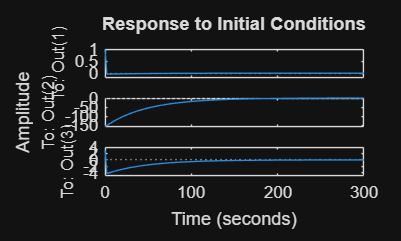

x0 = [1;
      2;
      3;
      4];


ss_bif = ss(A_f - B_f * K, B_f, C_lon, D_lon);

figure
initial(ss_bif, x0)

Acum vedem valorile proprii ale sistemului in bucla inchisa

eig(ss_bif)

ans =  -13.2837 +12.2479i
 -13.2837 -12.2479i
  -0.0211 + 0.0000i
 -14.2702 + 0.0000i



eig(A_f - B_f * K)

ans =  -13.2837 +12.2479i
 -13.2837 -12.2479i
  -0.0211 + 0.0000i
 -14.2702 + 0.0000i


Pana sa ma apuc de cerinta, sa scoatem cholesky ala

Qtilde = chol(Q)

Qtilde =     3.1623         0         0         0
         0    5.4772         0         0
         0         0    4.4721         0
         0         0         0    5.0000


Acum vedem stabilizarea si detectabilitatea

Pc = ctrb(A_f, B_f)

Pc =    -1.9200    0.2320    1.8665   -0.2208    0.3450   -0.0259   -3.7339    0.4176
         0         0   -1.8240    0.2204    1.7731   -0.2098    0.3278   -0.0246
    0.1440    7.8400    3.6427   -0.7307    3.3233   -0.4949   -1.5595    0.2043
   -5.2000         0 -137.1697   15.2578  224.3792  -25.8671 -119.6005   14.8335



Po = obsv(A_f, Qtilde)

Po =     3.1623         0         0         0
         0    5.4772         0         0
         0         0    4.4721         0
         0         0         0    5.0000
   -2.9441    0.0000   -0.0020   -0.0481
    5.2034         0         0         0
   -9.3468  -41.6356   -0.1402    0.3144
  365.7500   -3.6575   -1.0925   -3.1825
   -0.7711    0.0533    0.0124    0.0752
   -4.8443    0.0000   -0.0032   -0.0791
   -7.5612    1.0753   -0.0585   -0.0679
 -574.5044   12.4992    0.5038   -3.6105
    6.2440   -0.1703   -0.0163   -0.0353
   -1.2687    0.0878    0.0204    0.1237
    3.2168    0.5946    0.0213    0.1540



disp('Dimensiunea lui Af')

Dimensiunea lui Af


size(A_f)

ans =      4     4



disp('Rangul matricii de ctrb post-defect');

Rangul matricii de ctrb post-defect


disp(rank(Pc));

     4




disp('Rangul matricii de obsv post-defect');

Rangul matricii de obsv post-defect


disp(rank(Po));

     4



Sistemul este minimal, deci si stabilizabil si detectabil

### Problema 4: Metoda Vectorilor Schur

**Construim matricea Hamilton** pentru sistem avariat: $H_f =\left\lbrack \begin{array}{cc}
A_f  & -B_f R_n^{-1} B_f^T \\
-Q_n  & -A_f^T 
\end{array}\right\rbrack$

Hf = [A_f, -B_f * eye(2) / R * B_f';
       -Q -A_f']

Hf =    -0.9310    0.0000   -0.0006   -0.0152   -0.7463         0   -0.2479   -1.9968
    0.9500         0         0         0         0         0         0         0
   -2.0900   -9.3100   -0.0314    0.0703   -0.2479         0  -10.2484    0.1498
   73.1500   -0.7315   -0.2185   -0.6365   -1.9968         0    0.1498   -5.4080
  -10.0000         0         0         0    0.9310   -0.9500    2.0900  -73.1500
         0  -30.0000         0         0   -0.0000         0    9.3100    0.7315
         0         0  -20.0000         0    0.0006         0    0.0314    0.2185
         0         0         0  -25.0000    0.0152         0   -0.0703    0.6365


Se aduce $H_f$ la Forma Schur Reala (FSR)  superior (cvasi-) triunghilara, si se scrie ca $S_f =U_f^T H_f U_f$

help schur

 schur - Schur decomposition
    This MATLAB function returns the Schur matrix of A.

    Syntax
      T = schur(A)
      T = schur(A,mode)
      [U,T] = schur(___)

    Input Arguments
      A - Input matrix
        square matrix
      mode - Schur form system
        "real" (default) | "complex"

    Output Arguments
      U - Schur vectors
        unitary matrix
      T - Schur matrix
        square matrix

    Examples
      Schur Form of Matrix
  


help ordschur

 ordschur - Reorder eigenvalues in Schur factorization
    This MATLAB function reorders the Schur factorization X = U*T*U'
    produced by [U,T] = schur(X) and returns the reordered Schur matrix TS
    and the orthogonal matrix US, such that X = US*TS*US'.

    Syntax
      [US,TS] = ordschur(U,T,select)
      [US,TS] = ordschur(U,T,keyword)
      [US,TS] = ordschur(U,T,clusters)

    Input Arguments
      U - Unitary matrix
        matrix
      T - Schur matrix
        matrix
      select - Cluster selector
        logical vector
      keyword - Eigenvalue region keyword
        'lhp' | 'rhp' | 'udi' | 'udo'
  


[U,T] = schur(Hf)

U =     0.0054    0.1136   -0.1441    0.9372   -0.1778   -0.0936   -0.2157   -0.0337
   -0.0006    0.0055   -0.0032   -0.0339    0.0059    0.0044    0.0066   -0.9994
    0.0068    0.0479   -0.0107    0.2843    0.4667    0.5117    0.6611    0.0001
   -0.0308    0.7206   -0.6606   -0.1904   -0.0522    0.0659    0.0052    0.0126
   -0.9827   -0.1447   -0.1140    0.0088   -0.0024    0.0032    0.0140   -0.0000
    0.0179   -0.0236   -0.0384    0.0207   -0.4839   -0.4971    0.7183   -0.0010
    0.0045   -0.0624    0.0711   -0.0489   -0.7160    0.6899   -0.0019   -0.0001
    0.1812   -0.6635   -0.7234   -0.0241    0.0318    0.0446   -0.0121   -0.0003


T =    14.1099  -50.0582  -50.3923    6.3059    2.1064    0.3381   -1.9206    0.2449
    2.5440   14.1099  -22.6648   47.6989   -9.1618   -3.8476  -10.8298   -1.3519
         0         0  -14.1099  -48.2636    7.4816    5.1040    9.3601    0.0788
         0         0    2.6386  -14.1099    5.2534   -0.1030    4.0088    3.6586
         0         0         0         0   14.2538    1.3669   10.5367  -10.0557
         0         0         0         0         0  -14.2538   -9.8830  -10.2359
         0         0         0         0         0         0    0.0211   27.7263
         0         0         0         0         0         0         0   -0.0211



[Uord,Tord] = ordschur(U,T,'lhp')

Uord =     0.0590    0.1296    0.0005   -0.0006    0.1574    0.9377   -0.2730   -0.0340
   -0.0014   -0.0136    0.0011   -0.0004   -0.0135   -0.0292    0.0097   -0.9993
    0.0003    0.0664    0.5112   -0.2730   -0.0075    0.2194    0.7820    0.0011
    0.0513   -0.7483    0.0542   -0.0124   -0.6282    0.1953   -0.0370    0.0126
    0.9769    0.1588   -0.0080   -0.0019   -0.1291   -0.0600    0.0063   -0.0000
    0.0013   -0.0302   -0.4675   -0.8834    0.0136    0.0014   -0.0005    0.0001
   -0.0135    0.0577    0.7151   -0.3807   -0.0197   -0.1671   -0.5585   -0.0001
    0.1982   -0.6238    0.0762   -0.0073    0.7504   -0.0463    0.0207   -0.0003


Tord =   -14.1099   47.9789   -3.7312    0.5626  -51.8081   -3.6787   -0.5688    0.2448
   -2.6543  -14.1099   -0.7536    0.5719  -25.3676  -49.7640   14.3374    1.2941
         0         0  -14.2538    7.5695    2.0392    0.6095   -6.5016   -9.3584
         0         0         0   -0.0211   -0.9394    1.4915    9.3549  -29.0108
         0         0         0         0   14.1099  -46.1055   13.7469    1.1677
         0         0         0         0    2.7621   14.1099    0.2751    1.7816
         0         0         0         0         0         0   14.2538    7.3834
         0         0         0         0         0         0         0    0.0211


Scriem $\left\lbrace \begin{array}{l}
S_f =\left\lbrack \begin{array}{cc}
S_{f_{11} }  & S_{f_{12} } \\
0 & S_{f_{22} } 
\end{array}\right\rbrack \\
U_f =\left\lbrack \begin{array}{cc}
U_{f_{11} }  & U_{f_{12} } \\
U_{f_{21} }  & U_{f_{22} } 
\end{array}\right\rbrack 
\end{array}\right.$. De mentionat: primele n coloane ale lui $U_f$, mai exact $\left\lbrack \begin{array}{c}
U_{f_{11} } \\
U_{f_{21} } 
\end{array}\right\rbrack$ subintind spatiul invariant si stabil al lui $H_f$. **Aceasta exprimare pompoasa inseamna ca aceste n coloane corespund valorilor proprii stabile: **$\lambda_i \in \Lambda \left(S_f \right),\textrm{Re}\left(\lambda_i \right)<0$**. Mai precis, aceste valori stabile sunt in **$S_{f_{11} }$

Uf11 = Uord(1:4,1:4)

Uf11 =     0.0590    0.1296    0.0005   -0.0006
   -0.0014   -0.0136    0.0011   -0.0004
    0.0003    0.0664    0.5112   -0.2730
    0.0513   -0.7483    0.0542   -0.0124



Uf21 = Uord(5:8,1:4)

Uf21 =     0.9769    0.1588   -0.0080   -0.0019
    0.0013   -0.0302   -0.4675   -0.8834
   -0.0135    0.0577    0.7151   -0.3807
    0.1982   -0.6238    0.0762   -0.0073


Solutia ecuatiei **Riccati** este $P_f =U_{f_{21} } U_{f_{11} }^{-1}$

disp('Pf manual cu SChur');

Pf manual cu SChur


PfManual = Uf21 * eye(4) / Uf11

PfManual = 1.0e+04 *

    0.0032    0.0504   -0.0001   -0.0004
    0.0504    1.4521   -0.0013   -0.0177
   -0.0001   -0.0013    0.0001    0.0000
   -0.0004   -0.0177    0.0000    0.0003



disp('Pf cu Riccati');

Pf cu Riccati


Pf

Pf = 1.0e+04 *

    0.0032    0.0504   -0.0001   -0.0004
    0.0504    1.4521   -0.0013   -0.0177
   -0.0001   -0.0013    0.0001    0.0000
   -0.0004   -0.0177    0.0000    0.0003



KfManual = eye(2) / R * B_f' * PfManual

KfManual =    -8.3144   -9.7196    0.1355   -2.0398
    0.3511    2.9513    1.8143    0.0594



Kf = eye(2) / R * B_f' * Pf

Kf =    -8.3144   -9.7196    0.1355   -2.0398
    0.3511    2.9513    1.8143    0.0594


Obtinem $\Lambda \left(S_{f_{11} } \right)=\Lambda \left(A_f -B_f R_n^{-1} B_f^T P_f \right)\in {\mathbb{C}}^-$

Tord11 = Tord(1:4,1:4)

Tord11 =   -14.1099   47.9789   -3.7312    0.5626
   -2.6543  -14.1099   -0.7536    0.5719
         0         0  -14.2538    7.5695
         0         0         0   -0.0211



eig(Tord11)

ans =  -14.1099 +11.2849i
 -14.1099 -11.2849i
 -14.2538 + 0.0000i
  -0.0211 + 0.0000i



eig(A_f - B_f * KfManual)

ans =  -14.1099 +11.2849i
 -14.1099 -11.2849i
  -0.0211 + 0.0000i
 -14.2538 + 0.0000i



eig(A_f - B_f * Kf)

ans =  -14.1099 +11.2849i
 -14.1099 -11.2849i
  -0.0211 + 0.0000i
 -14.2538 + 0.0000i


### Problema 5

Hai sa dam un $x_f$ oarecare

xf = [-1;
       3;
       0.9;
       -0.4];

Acum calculam costul optimal pentru regim nominal

Jnoptim = x0' * P * x0

Jnoptim = 5.4075e+04

Acum calculam costul optimal pentru regim avariat

Jfoptim = xf' * Pf * xf

Jfoptim = 1.2806e+05

## Probleme rezolvatra

clear
close all
clc

Fie $A=\left\lbrack \begin{array}{cc}
0 & 1\\
0 & 0
\end{array}\right\rbrack ,B=\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack ,x_0 =\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack ,Q=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 2
\end{array}\right\rbrack ,R=1$

**Calculati solutia optimala si aratati ca stabilizeaza**

**Care este costul optimal?**

A = [0 1;
     0 0];
B = [0;
     1];

x0 = [1;
      1];

Q = diag([1 2]);

R = 1;

Aici aflu Solutia CARE (P) si comanda K

[P,K] = icare(A,B,Q,R)

P =     2.0000    1.0000
    1.0000    2.0000


K =     1.0000    2.0000



[K,P] = lqr(A,B,Q,R)

K = 1×2
    1.0000    2.0000


P = 2×2
    2.0000    1.0000
    1.0000    2.0000


Aici arat ca stabilizeaza

eig(A - B * K)

ans = 2×1
  -1.0000 + 0.0000i
  -1.0000 - 0.0000i



A - B * K

ans = 2×2
         0    1.0000
   -1.0000   -2.0000


Asta este costul optim

Joptim = x0' * P * x0

Joptim = 6.0000

## Alt exercitiu

Fie $A=1,B=\sqrt{2},x_0 =\sqrt{5},Q=R=1$

**Calculati solutia optimala si aratati ca stabilizeaza**

**Care este costul optimal?**

clear
close all
clc

A = 1;
B = sqrt(2);
x0 = sqrt(5);
Q = 1;
R = 1;

Acum aflam solutia CARE P si legea de comanda K

[P,K] = icare(A,B,Q,R)

P = 1.3660

K = 1.9319


[K,P] = lqr(A,B,Q,R)

K = 1.9319

P = 1.3660

Acum aratam ca stabilizeaza

eig(A - B*K)

ans = -1.7321

A - B * K

ans = -1.7321

Asta este costul optim

Joptim = x0' * P * x0

Joptim = 6.8301

## Alt exercitiu

Fie ecuatia $-b^2 P^2 +2\textrm{aP}+1=0$

J = $\int_0^{\infty } \left\lbrack x^2 +u^2 \right\rbrack \textrm{dt}$


$$x_0 =b$$


**Scoateti A,B,Q,R.**

**Dupa scoateti P,K. Aratati ca sistemul este stabilizat.**

**Aflati costul optim**

clear
close all
clc

Sa punem aici CARE:$A_n^T P_n +P_n A_n -{P_n B_n R}_n^{-1} B_n^T P_n +Q_n =0$. Stim din functia de cost ca $Q=R=1$.Inlocuim aici si obtinem:$A_n^T P_n +P_n A_n -P_n B_n 1B_n^T P_n +1=0$

 Acum punem impreuna cele 2 ecuatii: $\left\lbrace \begin{array}{l}
A_n^T P_n +P_n A_n -P_n B_n 1B_n^T P_n +1=0\\
-b^2 P^2 +2\textrm{aP}+1=0
\end{array}\right.$.

Daca ne uitam mai atent, putem vedea ca $-b^2 P^2 +2\textrm{ax}+1$ se poate rescrie ca $\textrm{ax}+\textrm{ax}-\textrm{PbbP}+1$. Scoatem P si avem $P_{1,2} =\left\lbrace \begin{array}{l}
\frac{a+\sqrt{a^2 +b^2 }}{b^2 }\\
\frac{a-\sqrt{a^2 +b^2 }}{b^2 }
\end{array}\right.$. $P>0\to P=\frac{a+\sqrt{a^2 +b^2 }}{b^2 }$


$$K=R^{-1} B^T P=1*b*\frac{a+\sqrt{a^2 +b^2 }}{b^2 }=\frac{a+\sqrt{a^2 +b^2 }}{b}$$


Acum facem $\hat{A} =A-\textrm{BK}=a-b\frac{a+\sqrt{a^2 +b^2 }}{b}=a-a-\sqrt{a^2 +b^2 }=-\sqrt{a^2 +b^2 }<0$


$$J_{\textrm{optim}} =x_0^T {\textrm{Px}}_0 =b\frac{a+\sqrt{a^2 +b^2 }}{b^2 }b=a+\sqrt{a^2 +b^2 }$$


## Alt exercitiu

clear
close all
clc

